# Identificazione Closed-Loop

clear; close all; clc;
startTimer = tic;

simulation.author = 'CL_M';
Nprova = 1;

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Definizione del sistema controllato

model_initialization;

Accelerazione massima e Rest Time.

cs.setMaxAcceleration(15);
cs.setRestTime(0.1);

## Definizione segnale eccitante

### Parametri

Calcoliamo la massima pulsazione ammissibile per il segnale. Deve essere al massimo la metà della pulsazione di campionamento al fine di evitare fenomeni di aliasing (Teorema di Shannon).

Estraiamo inoltre dal sistema la massima coppia che ciascun motore può erogare.

w_max = pi/st %rad/s     Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts

w_max = 3.1416e+03

umax = system.getUMax

umax =    150
   150


% Chirp
w0_chirp = 20; w1_chirp = w_max;       % wide, main chirp
w0b_chirp = 50; w1b_chirp = 200;     % narrow, secondary chirp 1 
w0c_chirp = 500; w1c_chirp = 2000;     % narrow, secondary chirp 2
ampiezza_chirp = 70;

% Portante
w_portante=w0_chirp/20;
ampiezza_portante=60;
T_portante=2*pi/w_portante;

### Portante

durata_simulazione = 1.1*T_portante; % secondi
t = (0:st:durata_simulazione)';
portante = ampiezza_portante*sin(w_portante*t);

durata_teorica = seconds(durata_simulazione); % debug
durata_teorica.Format = 'hh:mm:ss';
display(durata_teorica)

durata_teorica = duration
   00:00:06


n_samples = length(t) % debug

n_samples = 6912

sample_computation_time = 0.02; % stimato empiricamente su 100 run
durata_reale = n_samples*sample_computation_time; % debug
durata_reale = seconds(durata_reale); % debug
durata_reale.Format = 'hh:mm:ss';
display(durata_reale)

durata_reale = duration
   00:02:18


### Chirp

*Aggiunto altro segnale chirp per infittire l'indagine della zona di interesse (i due chirp sono sfasati di 90°)*

chirp_wide = chirp(t,w0_chirp/2/pi,t(end),w1_chirp/2/pi,'logarithmic',90); % chirp che spazza un range maggiore (90° per iniziare come un seno)
chirp_narrow1 = chirp(t,w0b_chirp/2/pi,t(end),w1b_chirp/2/pi,'logarithmic',135); % chirp concentrato attorno alla risonanza
chirp_narrow2 = chirp(t,w0c_chirp/2/pi,t(end),w1c_chirp/2/pi,'logarithmic',180); % chirp concentrato attorno al polo dell'attrito viscoso

chirp_total = (chirp_wide + chirp_narrow1 + chirp_narrow2)/max(chirp_wide + chirp_narrow1 + chirp_narrow2);

chirpSignal = ampiezza_chirp*chirp_total;

### Somma dei segnali

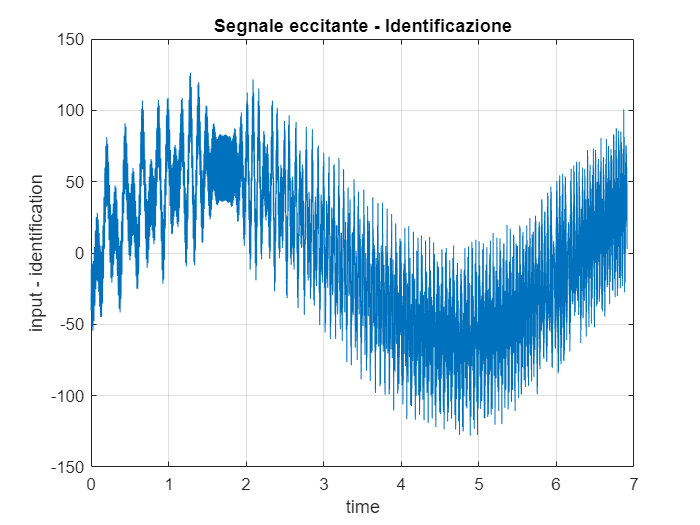

input_signal = portante + chirpSignal;

fig_inputSignal = figure;
plot(t,input_signal);
xlabel('time'); ylabel('input - identification'); title('Segnale eccitante - Identificazione'); grid on;

### Riferimento (nullo per entrambi i giunti)

reference = zeros(length(t),system.getOutputNumber);

### Selezione dei sottosistemi di cui eseguire l'identificazione

joint1 = true;
joint2 = false;

if joint1 && ~ joint2
    control_action = [input_signal zeros(length(input_signal),1)];
elseif joint2 && ~ joint1
    control_action = [zeros(length(input_signal),1) input_signal];
elseif joint1 && joint2
    control_action = [input_signal input_signal];
else
    error('Selezionare almeno 1 giunto!')
end

## Controllore

Consente di mantenere la **velocità** dei giunti attorno al valore nullo

Kp_values =  [10 100];
Kv_values =  [1 10];
controller = SimpleScaraController(st,Kp_values,Kv_values); % PD Controller, sluggishly tuned
cs.setController(controller);

## Simulazione sistema

checkSimulation = true;    checkLoadingData = false;

if checkSimulation

    f = waitbar(0,'0','Name','Simulazione - Identificazione',...
                'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
    setappdata(f,'canceling',0);

    execution_time = zeros(length(t),1); % debug

    cs.initialize % SCARA riposizionato nella configurazione di riposo iniziale

    for idx=1:length(t)
        tic
        
        % Check for clicked Cancel button
        if getappdata(f,'canceling')
            break
        end
        
        % step: simulazione sistema in anello chiuso
        % PARAMETRI
        % ingresso 1: riferimento
        % ingresso 2: azione sul carico come segnale eccitante (a valle del controllore)
        [process_output(idx,:),control_action(idx,:),tt(idx,1)]=cs.step(reference(idx,:)',control_action(idx,:)'); 

        % Update waitbar and message
        percent_progress = idx/length(t)*100;
        waitbar(percent_progress/100,f,sprintf('%.2f %%',percent_progress))

        execution_time(idx) = toc; % debug
    end

    beep

    delete(f)

    disp('Tempo di esecuzione medio di una singola simulazione')
    mean_execution_time = mean(execution_time) % debug

else % checkLoadingData
    load(simulationDirectory);    
end

Tempo di esecuzione medio di una singola simulazione


mean_execution_time = 0.0153

## Calcolo della risposta in frequenza

### F.d.t. coppia-velocità giunto 1

Calcolo la risposta in frequenza e la plotto. Plotto anche la frequenza di inizio del segnale eccitante

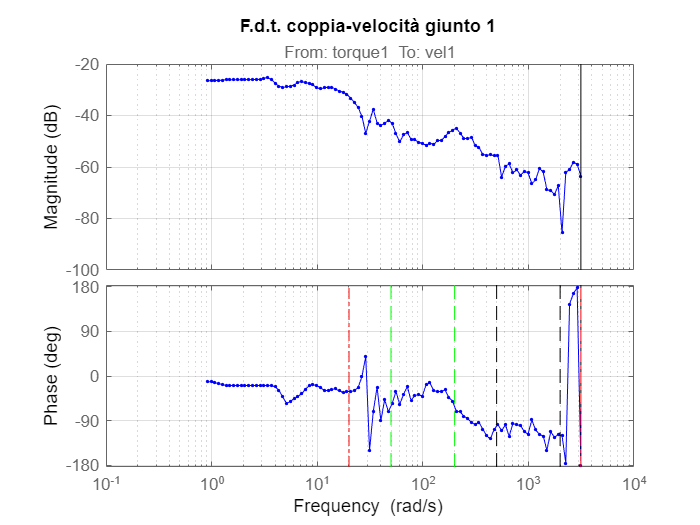

if (joint1)
    identification_joint1 = iddata(process_output(:,3),control_action(1:length(tt),1),st);
    identification_joint1.OutputName = 'vel1'; identification_joint1.InputName = 'torque1';
    
    freq_resp_ident_joint1 = spafdr(identification_joint1);
    frequency1 = freq_resp_ident_joint1.Frequency;
    
    fig_j1 = figure;
    bode(freq_resp_ident_joint1,'.-',bode_opts)
    grid on
    hold on
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    hold off
    title('F.d.t. coppia-velocità giunto 1')
end

### F.d.t. coppia-velocità giunto 2

Calcolo la risposta in frequenza con il comando e la plotto. Plotto anche la frequenza di inizio del segnale eccitante

if (joint2)
    identification_joint2 = iddata(process_output(:,4),control_action(1:length(tt),2),st);
    identification_joint2.OutputName = 'vel2'; identification_joint2.InputName = 'torque2';
    
    freq_resp_ident_joint2 = spafdr(identification_joint2);
    frequency2 = freq_resp_ident_joint2.Frequency;

    fig_j2 = figure;
    bode(freq_resp_ident_joint2,'.-',bode_opts)
    grid on
    hold on
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    hold off
    title('F.d.t. coppia-velocità giunto 2')
end

## Grafico dei risultati

system.getInputName

ans = 1×2 cell array
    {'torque_1'}    {'torque_2'}


system.getOutputName

ans = 1×4 cell array
    {'position_1'}    {'position_2'}    {'velocity_1'}    {'velocity_2'}


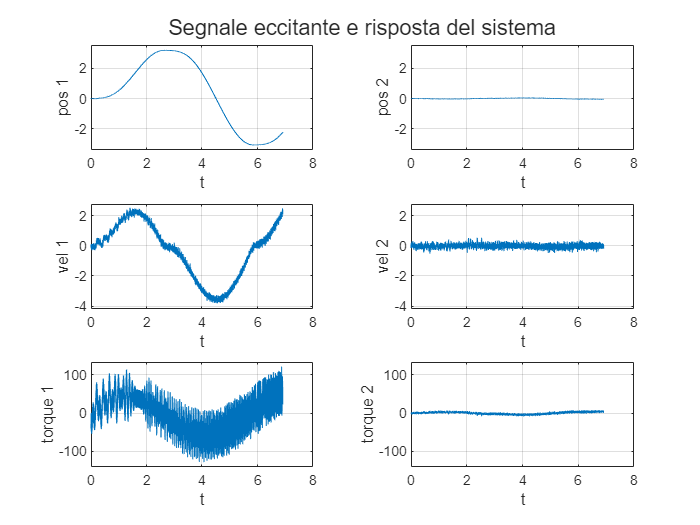

pos1=process_output(:,1); pos2=process_output(:,2);
vel1=process_output(:,3); vel2=process_output(:,4);
tau1=control_action(:,1); tau2=control_action(:,2);

% coppia considerando la saturazione e solo i samples effettivamente
% calcolati durante la simulazione (anche se questa è stata interrotta a un certo punto)
actual_tau1 = min(max(tau1(1:length(tt)),-umax(1)),umax(1));
actual_tau2 = min(max(tau2(1:length(tt)),-umax(2)),umax(2));

fig_res = figure;
tl = tiledlayout(3,2);

nexttile; plot(tt,pos1); grid on; xlabel('t'); ylabel('pos 1'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])
nexttile; plot(tt,pos2); grid on; xlabel('t'); ylabel('pos 2'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])

nexttile; plot(tt,vel1); grid on; xlabel('t'); ylabel('vel 1'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])
nexttile; plot(tt,vel2); grid on; xlabel('t'); ylabel('vel 2'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])

nexttile; plot(tt,actual_tau1); grid on; xlabel('t'); ylabel('torque 1');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

nexttile; plot(tt,actual_tau2); grid on; xlabel('t'); ylabel('torque 2');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

title(tl,'Segnale eccitante e risposta del sistema')

## Salvataggio simulazione

if checkSimulation
    % Selezionare il file
    simulationName = strcat(simulation.author,'_simulation_',num2str(Nprova));
    simulationDirectory = strcat('.\simulations\identification\data\',simulationName);
    directoryFig = strcat('.\simulations\identification\figures\',simulationName);
    
    % Salvataggio della simulazione
    simulation.description = '3xchirp + portante - j1';
    simulation.w0chirp = w0_chirp;
    simulation.w1chirp = w1_chirp;
    simulation.wportante = w_portante;
    simulation.ampiezza_chirp = ampiezza_chirp;
    simulation.ampiezza_portante = ampiezza_portante;
    simulation.durata_simulazione = durata_simulazione;
    simulation.control_action = control_action;
    simulation.process_output = process_output;
    simulation.tt = tt;
    simulation.joint1 = joint1;
    simulation.joint2 = joint2;
    simulation.durata_teorica = durata_teorica;
    simulation.durata_reale = durata_reale;
    simulation.Kp_values = Kp_values;
    simulation.Kv_values = Kv_values;
    
    save(simulationDirectory,'-struct','simulation')

    if (joint1)
        savefig(fig_j1,strcat(directoryFig,'_j1'))
    end
    if (joint2)
        savefig(fig_j2,strcat(directoryFig,'_j2'))
    end
    savefig(fig_res,strcat(directoryFig,'_res'))
    savefig(fig_inputSignal,strcat(directoryFig,'_inputSignal'))
end

## Stima del modello

checkModelEstimation = true;    checkLoadingModel = false;

Definizione dei pesi per concentrare in un'area frequenziale il calcolo del modello `->`** NON FUNZIONA, MEGLIO USARE **`fselect`** (???)**

if (joint1)
    frequency = frequency1;
elseif (joint2)
    frequency = frequency2;
else
    frequency = frequency;
end

peso = [];
peso=1e5*ones(length(frequency),1);
wpeso0=50; wpeso1=1000;
peso(frequency<wpeso0)=1e-5; peso(frequency>wpeso1)=1e-5;

if checkModelEstimation
    order_joint1 = 3; % 1:16 per valutare più ordini e far scegliere automaticamente il migliore
    order_joint2 = 5;

    % opzioni per il fitting del modello
    %{
    opts = ssestOptions('EnforceStability',1,'WeightingFilter',peso);
    opts.SearchOptions.MaxIterations = 50;
    opts.SearchOptions.Tolerance = 0.001;
    opts.Regularization.Lambda = 10;
    opts.Regularization.R = 10;
    %}

    if (joint1)
        % Fitting automatico modello
        %%{
        freq_range = [find(freq_resp_ident_joint1.Frequency>wpeso0 & freq_resp_ident_joint1.Frequency<wpeso1)];

        region = fselect(freq_resp_ident_joint1,freq_range);

        modelC_joint1 = ssest(region,order_joint1);
        modelD_joint1 = ssest(region,order_joint1,'Ts',st);
        %}

        % Fitting manuale modello 3°ordine
        %{
        dc_gain = -35;
        M_Rp_val = 8;       M_Rz_val = 8;
        w_h_val = 6;
        w_Rp_val = 250;     w_Rz_val = 80;
        modelC_joint1 = fit_3order_model(dc_gain,M_Rp_val,M_Rz_val,w_h_val,w_Rp_val,w_Rz_val);
        modelD_joint1 = c2d(modelC_joint1,st);
        %}

        % quantificazione bontà del fitting
        id_points_joint1 = reshape(abs(freq_resp_ident_joint1.ResponseData),1,[]);
        modelC_points_joint1 = reshape(abs(freqresp(modelC_joint1,freq_resp_ident_joint1.Frequency)),1,[]);
        modelD_points_joint1 = reshape(abs(freqresp(modelD_joint1,freq_resp_ident_joint1.Frequency)),1,[]);
        
        fitC_joint1 = compute_fit_goodness(id_points_joint1,modelC_points_joint1,freq_resp_ident_joint1.Frequency,w0_chirp,w1_chirp);
        fitD_joint1 = compute_fit_goodness(id_points_joint1,modelD_points_joint1,freq_resp_ident_joint1.Frequency,w0_chirp,w1_chirp);
    end

    if (joint2)
        % Fitting automatico modello
        %%{
        freq_range = [find(freq_resp_ident_joint2.Frequency>wpeso0 & freq_resp_ident_joint2.Frequency<wpeso1)];

        region = fselect(freq_resp_ident_joint2,freq_range);

        modelC_joint2 = ssest(region,order_joint2);
        modelD_joint2 = ssest(region,order_joint2,'Ts',st);
        %}

        % Fitting manuale modello 5°ordine
        %{
        dc_gain = -25;
        M_Rp1_val = 14;      M_Rz1_val = 7;
        M_Rp2_val = 8;       M_Rz2_val = 9;
        w_h_val = 10;
        w_Rp1_val = 255;     w_Rz1_val = 160;
        w_Rp2_val = 420;     w_Rz2_val = 330;
        modelC_joint2 = fit_5order_model(dc_gain,M_Rp1_val,M_Rz1_val,M_Rp2_val,M_Rz2_val, ...
                                         w_h_val,w_Rp1_val,w_Rz1_val,w_Rp2_val,w_Rz2_val);
        modelD_joint2 = c2d(modelC_joint2,st);
        %}

        % Fitting manuale modello 3°ordine
        %{
        dc_gain = -27;
        M_Rp_val = 18;       M_Rz_val = 18;
        w_h_val = 7;
        w_Rp_val = 260;      w_Rz_val = 120;
        modelC_joint2 = fit_3order_model(dc_gain,M_Rp_val,M_Rz_val,w_h_val,w_Rp_val,w_Rz_val);
        modelD_joint2 = c2d(modelC_joint2,st);
        %}

        % quantificazione bontà del fitting
        id_points_joint2 = reshape(abs(freq_resp_ident_joint2.ResponseData),1,[]);
        modelC_points_joint2 = reshape(abs(freqresp(modelC_joint2,freq_resp_ident_joint2.Frequency)),1,[]);
        modelD_points_joint2 = reshape(abs(freqresp(modelD_joint2,freq_resp_ident_joint2.Frequency)),1,[]);
        
        fitC_joint2 = compute_fit_goodness(id_points_joint2,modelC_points_joint2,freq_resp_ident_joint2.Frequency,w0_chirp,w1_chirp);
        fitD_joint2 = compute_fit_goodness(id_points_joint2,modelD_points_joint2,freq_resp_ident_joint2.Frequency,w0_chirp,w1_chirp);
    end

else % checkLoadingModel
    load(directoryModel);
end

## Grafico modelli

### F.d.t. coppia-velocità giunto 1

Plotto i dati sperimentali con l'intervallo di confidenza (in questo caso 3*sigma)

if (joint1)
    fig_j1 = figure;
    h = bodeplot(freq_resp_ident_joint1,bode_opts);
    hold on
    showConfidence(h,3)

           Grafico i modelli stimati

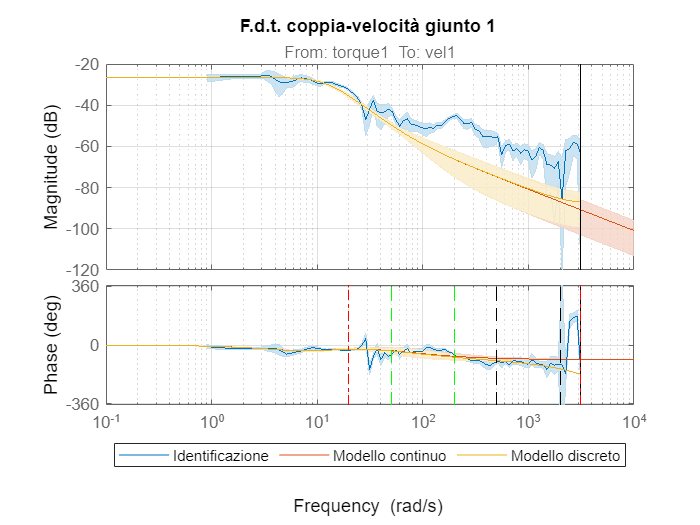

Bontà percentuale del fitting tra w0 e w1 (continuo e discreto):


   40.5639

   40.5842



    bode(modelC_joint1,modelD_joint1,bode_opts)
    
    % range frequenze investigate
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    
    grid on
    hold off
    legend('Identificazione','Modello continuo','Modello discreto','Location','southoutside','Orientation','horizontal')
    title('F.d.t. coppia-velocità giunto 1')

    disp('Bontà percentuale del fitting tra w0 e w1 (continuo e discreto):')
    disp(fitC_joint1); disp(fitD_joint1) 
end

### F.d.t. coppia-velocità giunto 2

Plotto i dati sperimentali con l'intervallo di confidenza (in questo caso 3*sigma)

if (joint2)
    fig_j2 = figure;
    h = bodeplot(freq_resp_ident_joint2,bode_opts);
    hold on
    showConfidence(h,3)

           Grafico i modelli stimati

    bode(modelC_joint2,modelD_joint2,bode_opts)
    
    % range frequenze investigate
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    
    grid on
    hold off
    legend('Identificazione','Modello continuo','Modello discreto','Location','southoutside','Orientation','horizontal')
    title('F.d.t. coppia-velocità giunto 2')

    disp('Bontà percentuale del fitting tra w0 e w1 (continuo e discreto):')
    disp(fitC_joint2); disp(fitD_joint2) 
end

## Salvataggio modello

if checkModelEstimation
    % Selezionare il file
    modelName = strcat(simulation.author,'_model_', num2str(Nprova));
    directoryModel = strcat('.\estimated_models\data\',modelName);
    directoryFig = strcat('.\estimated_models\figures\',modelName);

    estimatedModel.simulation = simulation;
    estimatedModel.wpeso0 = wpeso0;                 estimatedModel.wpeso1 = wpeso1;
    estimatedModel.peso = peso;
    estimatedModel.joint1 = joint1;                 estimatedModel.joint2 = joint2;
    estimatedModel.freq_resp_ident_joint1 = [];     estimatedModel.freq_resp_ident_joint2 = [];
    estimatedModel.order_joint1 = order_joint1;     estimatedModel.order_joint2 = order_joint1;
    estimatedModel.modelC_joint1 = [];              estimatedModel.modelD_joint1 = [];
    estimatedModel.modelC_joint2 = [];              estimatedModel.modelD_joint2 = [];
    estimatedModel.fitC_joint1 = [];                estimatedModel.fitD_joint1 = [];
    estimatedModel.fitC_joint2 = [];                estimatedModel.fitD_joint2 = [];
    
    if (joint1)
        estimatedModel.freq_resp_ident_joint1 = freq_resp_ident_joint1;
        estimatedModel.modelC_joint1 = modelC_joint1;    estimatedModel.modelD_joint1 = modelD_joint1;
        estimatedModel.fitC_joint1 = fitC_joint1;        estimatedModel.fitD_joint1 = fitD_joint1;
        
        savefig(fig_j1,strcat(directoryFig,'_j1'))
    end
    
    if (joint2)
        estimatedModel.freq_resp_ident_joint2 = freq_resp_ident_joint2;
        estimatedModel.modelC_joint2 = modelC_joint2;    estimatedModel.modelD_joint2 = modelD_joint2;
        estimatedModel.fitC_joint2 = fitC_joint2;        estimatedModel.fitD_joint2 = fitD_joint2;
        
        savefig(fig_j2,strcat(directoryFig,'_j2'))
    end
    
    save(directoryModel,'-struct','estimatedModel')    
end

stopTimer = toc(startTimer);
stopTimer = seconds(stopTimer); % debug
stopTimer.Format = 'hh:mm:ss';
display(stopTimer)

stopTimer = duration
   00:02:06
